clear, clc, format short g


## PARTE 1

## 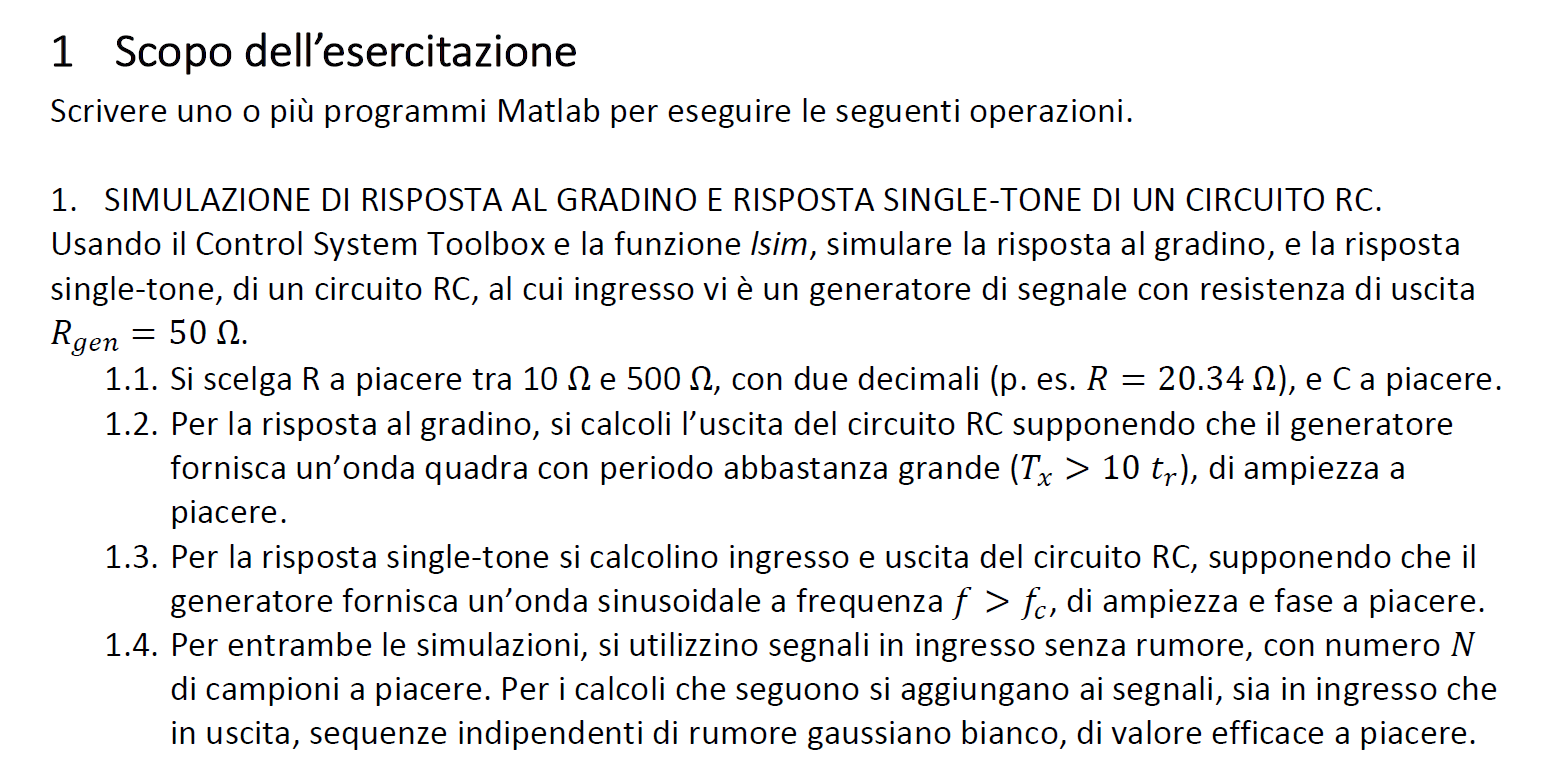


Rgen = 50;
R = 74.38;
C = 15e-9;

tr = C*(R+Rgen)*log(9)

tr =    4.0994e-06



N = 1000;

## definizione tau


tau_step = R*C;
tau_sin = (R+Rgen)*C

tau_sin =    1.8657e-06


## definizione periodi di campionamento

Td = 11*tr % durata simulazione

Td =    4.5093e-05



Ts = Td/N %periodo di campionamento

Ts =    4.5093e-08



n = (0:N-1)' %indici di campionamento

n =      0
     1
     2
     3
     4
     5
     6
     7
     8
     9



t = n*Ts % istanti di campionamento

t =             0
   4.5093e-08
   9.0186e-08
   1.3528e-07
   1.8037e-07
   2.2546e-07
   2.7056e-07
   3.1565e-07
   3.6074e-07
   4.0584e-07


## definizione onda quadra in ingresso

Vpp = 10;

x_step = Vpp*square(2*pi*t/Td)

x_step =     10
    10
    10
    10
    10
    10
    10
    10
    10
    10


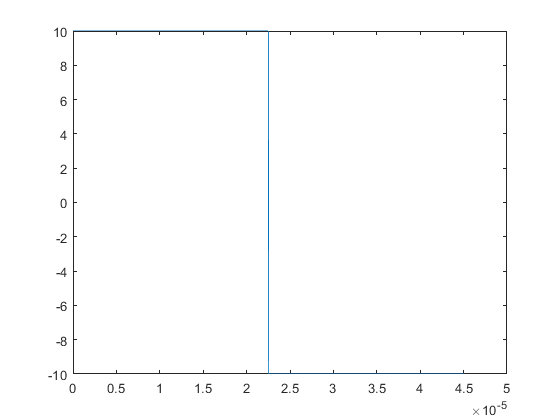


plot(t, x_step)

## definizione fdt

s = tf('s');

H1_dot = 1/(1+tau_step*s)


H1_dot =
 
         1
  ---------------
  1.116e-06 s + 1
 
Continuous-time transfer function.



## definizione risposta gradino

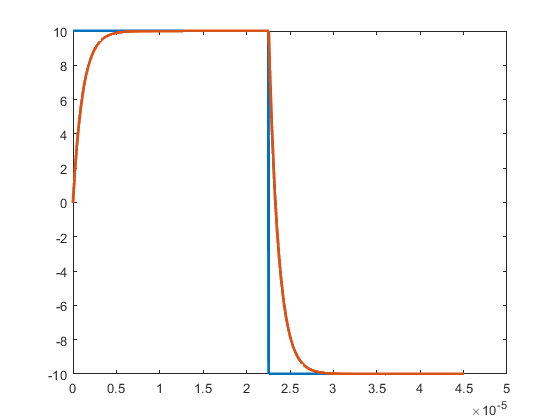

y_step = lsim(H1_dot, x_step, t);

plot(t, x_step, t, y_step, 'linewidth', 2)

## definizione parametri sinusoide

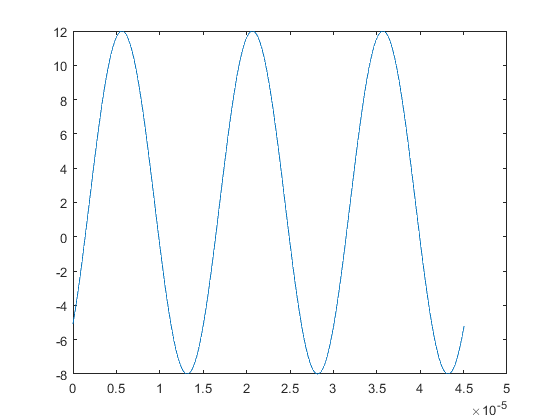

Np = 3;

Tx = Td/Np; 

fx = 1/Tx;

x_sin = 2 + Vpp*sin(2*pi*fx*t - pi/4);

plot(t, x_sin)

## definizione fdt

H_dot = 1/(1+tau_sin*s);


## definizione risposta seno

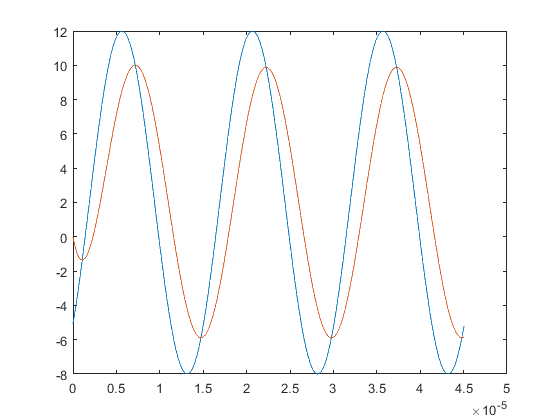

y_sin = lsim(H_dot, x_sin, t);

plot(t, x_sin, t, y_sin)

## 1.4

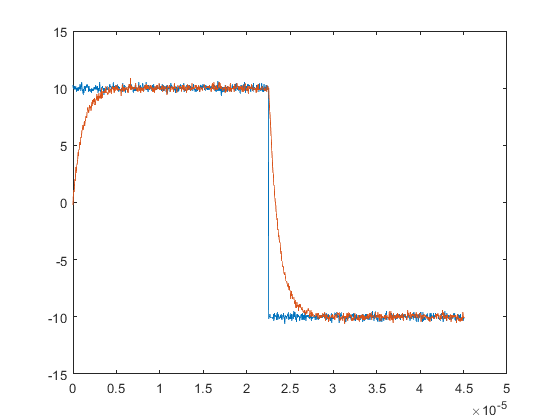

sigma = 0.2;
x_step = Vpp*square(2*pi*t/Td) + randn(N,1)*sigma;

y_step = lsim(H1_dot, x_step, t) + randn(N,1)*sigma;

plot(t,x_step, t, y_step)

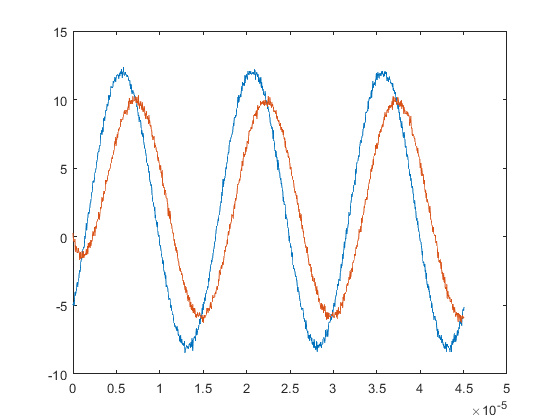


x_sin = 2 + Vpp*sin(2*pi*fx*t - pi/4) + randn(N,1)*sigma;
y_sin = lsim(H_dot, x_sin, t) + randn(N,1)*sigma;

plot(t,x_sin, t, y_sin)

## PARTE 2

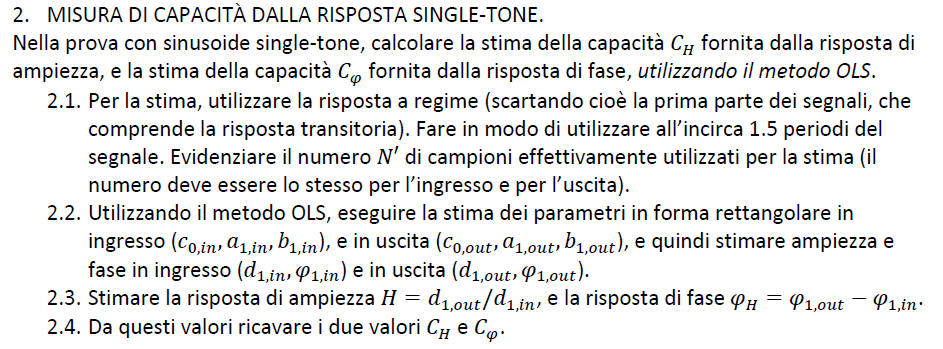

N2 = length(t)/2

N2 =    500



t1 = (N2+1:N)'

t1 =    501
   502
   503
   504
   505
   506
   507
   508
   509
   510



Fx = Np/N; %frequenza digitale
n = (0:N-1)'; %indici dei campioni

x_sin = 2 + Vpp*cos(2*pi*n*Fx - pi/4 - pi/2) + randn(N,1)*sigma; %trasformo seni in coseni
y_sin = lsim(H_dot, x_sin, t) + randn(N,1)*sigma;


xs = x_sin(N2+1:N)

xs =        8.9884
       8.3764
       8.7187
       8.6733
       8.7004
       8.8918
       8.2163
       8.0057
        7.854
       7.7133


ys = y_sin(N2+1:N)

ys =        10.053
       9.7849
       10.155
       9.9046
       9.5062
       10.117
       9.4008
       9.6315
       9.5862
       9.5274


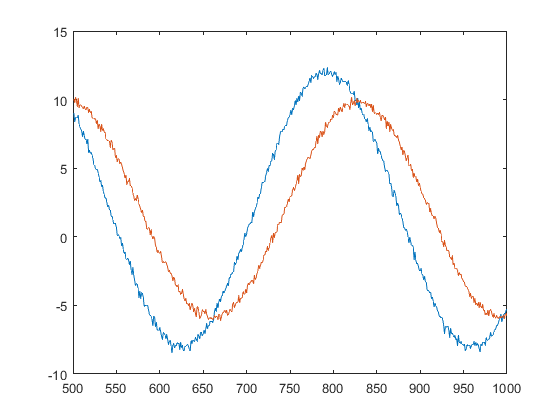



plot(t1, xs, t1, ys)


a1 = cos(-3*pi/4);
b1 = sin(-3*pi/4); 

wt = 2*pi*Fx*t1;

A = [ones(N2,1), cos(wt), -sin(wt)]

A =             1     -0.99982     0.018848
            1     -0.99929      0.03769
            1      -0.9984     0.056519
            1     -0.99716     0.075327
            1     -0.99556     0.094108
            1     -0.99361      0.11286
            1     -0.99131      0.13156
            1     -0.98865      0.15023
            1     -0.98564      0.16883
            1     -0.98229      0.18738


## Stima dei parametri di y


theta_hat_y = (A'*A)^(-1)*A'*ys; %% A\y

c0_hat_y = theta_hat_y(1)

c0_hat_y =        1.9817


a1_hat_y= theta_hat_y(2)

a1_hat_y =       -7.8132


b1_hat_y = theta_hat_y(3)

b1_hat_y =      -0.81538



d1_hat_y = sqrt(a1_hat_y^2 + b1_hat_y^2)

d1_hat_y =        7.8557



phi1_hat_y = atan2(b1_hat_y, a1_hat_y)

phi1_hat_y =       -3.0376


## Stima dei parametri di x

theta_hat_x = (A'*A)^(-1)*A'*xs; %% A\y

c0_hat_x = theta_hat_x(1)

c0_hat_x =        1.9892


a1_hat_x = theta_hat_x(2)

a1_hat_x =       -7.1696


b1_hat_x = theta_hat_x(3)

b1_hat_x =       -6.9508



d1_hat_x = sqrt(a1_hat_x^2 + b1_hat_x^2)

d1_hat_x =        9.9858



phi1_hat_x = atan2(b1_hat_x, a1_hat_x)

phi1_hat_x =       -2.3717


## Stima risposta di ampiezza e di fase

H = d1_hat_y/d1_hat_x

H =       0.78668



phi = phi1_hat_y - phi1_hat_x

phi =      -0.66592


## Ricavo C_H e C_phi


C_H = (sqrt(1-(H^2)/H)*(1/(2*pi*fx*R)))

C_H =    1.4855e-08



C_phi = tan(-phi)*(1/(2*pi*fx*R))

C_phi =    2.5268e-08
